ans = "Signal 6: 21:28 Vibration measurements [mm/s]"

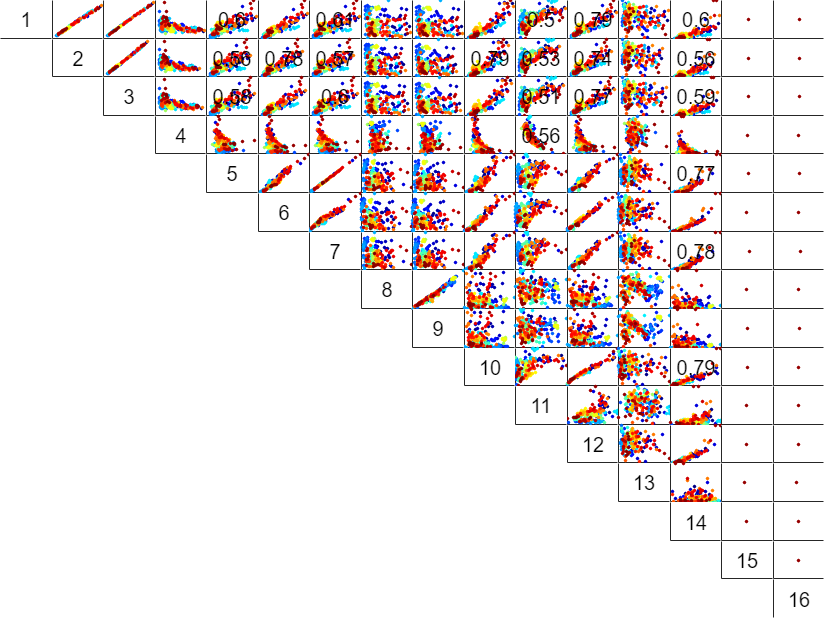

Features = DFD_FeatureTable_TimeDomain;
FeatureNames = FeatureNames_Combined;
lowerR2 = 0.3;
upperR2 = 0.8;
r2ReducedThreshold = 0.9;
selectedSignal = 6; % 21:28 Vibration measurements (mm per s)
saveFigures = true;
R2 = fnPlotFeatureVsFeature_Array(featureArray, lowerR2, upperR2, selectedSignal, FeatureNames, sensorNames);

disp(num2str(R2, '%.2f  '));

1.00  1.00  1.00  0.22  0.60  0.82  0.61  0.02  0.01  0.84  0.50  0.79  0.04  0.60   NaN   NaN
0.00  1.00  1.00  0.21  0.56  0.78  0.57  0.02  0.01  0.79  0.53  0.74  0.04  0.56   NaN   NaN
0.00  0.00  1.00  0.22  0.58  0.80  0.60  0.02  0.01  0.82  0.51  0.77  0.04  0.59   NaN   NaN
0.00  0.00  0.00  1.00  0.06  0.12  0.06  0.01  0.01  0.21  0.56  0.17  0.02  0.10   NaN   NaN
0.00  0.00  0.00  0.00  1.00  0.93  1.00  0.04  0.03  0.80  0.06  0.91  0.02  0.77   NaN   NaN
0.00  0.00  0.00  0.00  0.00  1.00  0.94  0.03  0.02  0.92  0.19  0.97  0.03  0.82   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.00  1.00  0.04  0.03  0.82  0.06  0.92  0.02  0.78   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.00  0.96  0.02  0.00  0.02  0.00  0.02   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.00  0.01  0.00  0.01  0.00  0.01   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.00  0.25  0.97  0.01  0.79   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.

## Combination 1

combination = 1;
selectedFeature = 1;
[selectedFeatureArray, selectedFeatureData, numOfSelectedFeatures] = fnSelectFeatures(selectedSignal, selectedFeature, featureArray, R2, upperR2, lowerR2, r2ReducedThreshold, true);

Sig 5 Sig 7 = 1.00
Sig 5 Sig 12 = 0.91
     1     5     7    11    12    14

     1     5    11    14



figure(); hold on;
sensorNames(selectedSignal)%title(sensorNames(selectedSignal));

ans = "21:28 Vibration measurements [mm/s]"

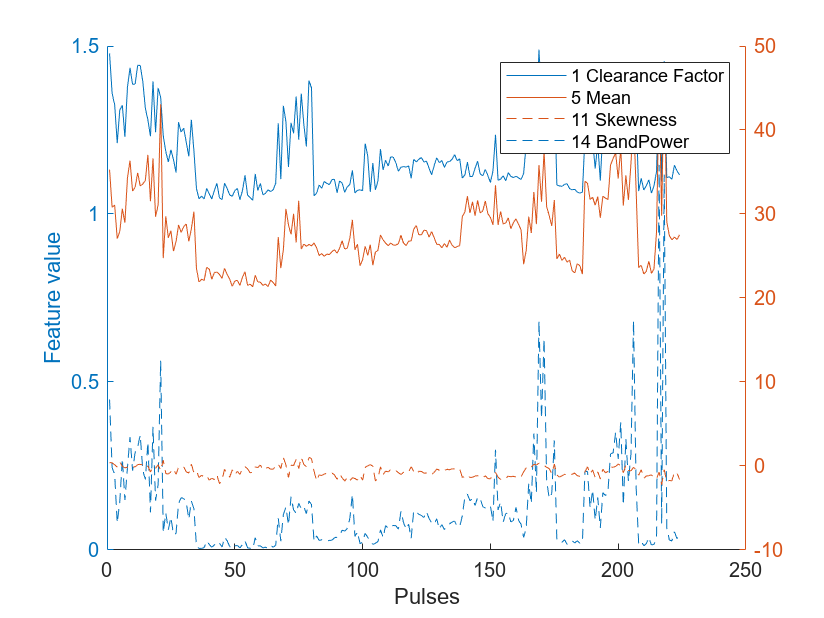

xlabel("Pulses");
ylabel("Feature value");
leg = {numOfSelectedFeatures};
secondaryAxisArrayIndex = [2 3];
legendAxis = [];
for i = 1:numOfSelectedFeatures
    if ismember(i, secondaryAxisArrayIndex)
        yyaxis right;
        ha = plot(selectedFeatureData{i});
        legendAxis = [legendAxis ha];
    else
        yyaxis left;
        hb = plot(selectedFeatureData{i});
        legendAxis = [legendAxis hb];
    end
    leg{i} = char(FeatureNames(selectedFeatureArray(i)));
end
hold off;
legend(legendAxis, leg);

if (saveFigures == true)
    filename = "..\Latex Document\figures\Models_Signal" + selectedSignal + "Feature" + selectedFeature;
    print(filename,'-depsc','-tiff')
end

txtTitle = "21:28 Vibration measurements [mm/s]"

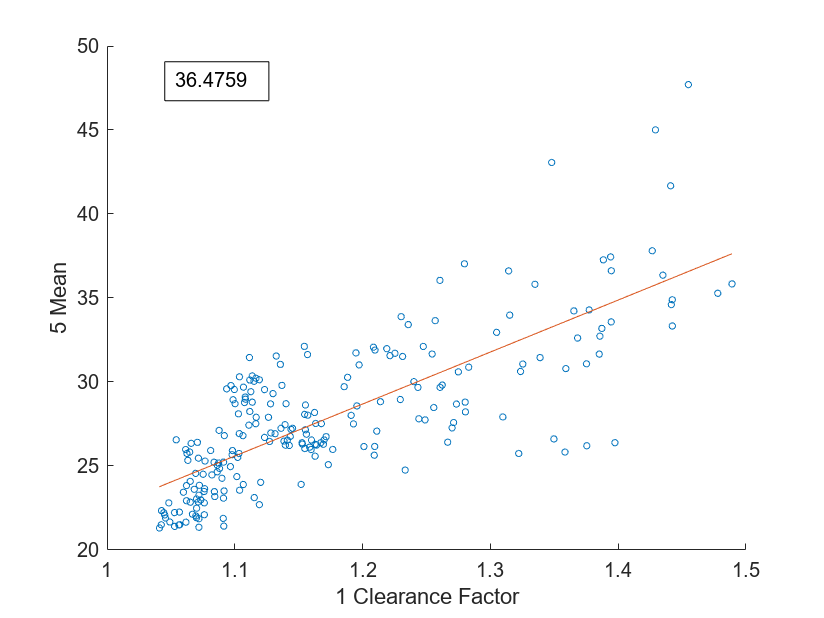

txtTitle = "21:28 Vibration measurements [mm/s]"

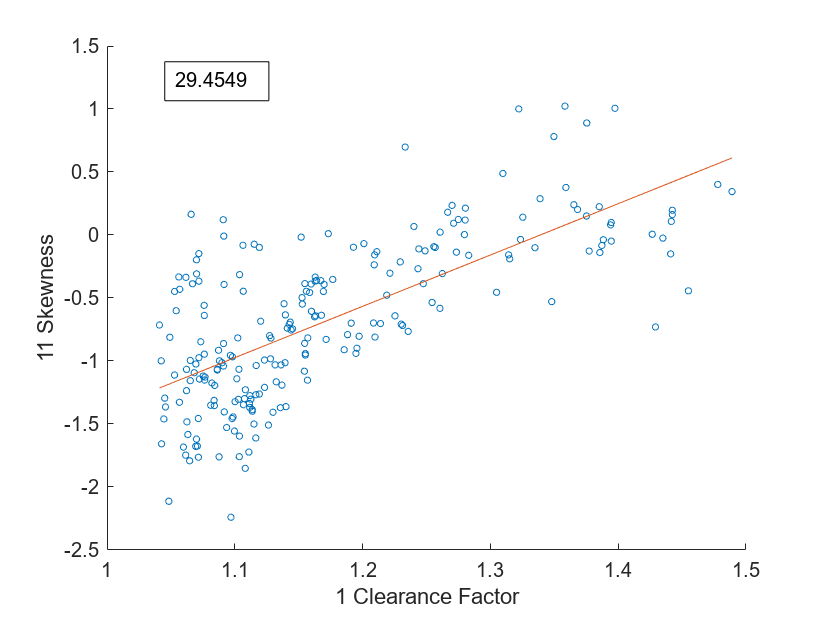

txtTitle = "21:28 Vibration measurements [mm/s]"

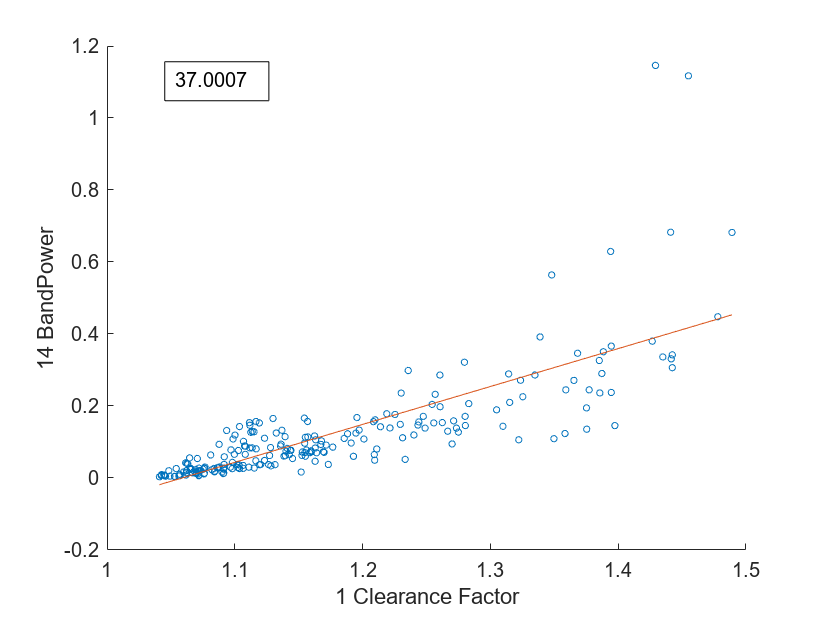

selectedFeatureIdx = find(selectedFeatureArray == selectedFeature);
linearModelNum = 1;
for index = 1 : numOfSelectedFeatures
    if selectedFeatureArray(index) ~= selectedFeature
        fnPlotModel(selectedFeatureData{index}, ...
            selectedFeatureData{selectedFeatureIdx}, ...
            sensorNames(selectedSignal), ...
            FeatureNames_Combined(selectedFeatureArray(index)), ...
            FeatureNames_Combined(selectedFeature));
        if (saveFigures == true)
            filename = "..\Latex Document\figures\Models_Signal" + selectedSignal ...
                + "Feature" + selectedFeature ...
                + "_Linear" + linearModelNum;
            export_fig(filename, '-eps', '-depsc');
            linearModelNum = linearModelNum + 1;
        end
    end
end

txtTitle = "21:28 Vibration measurements [mm/s]"

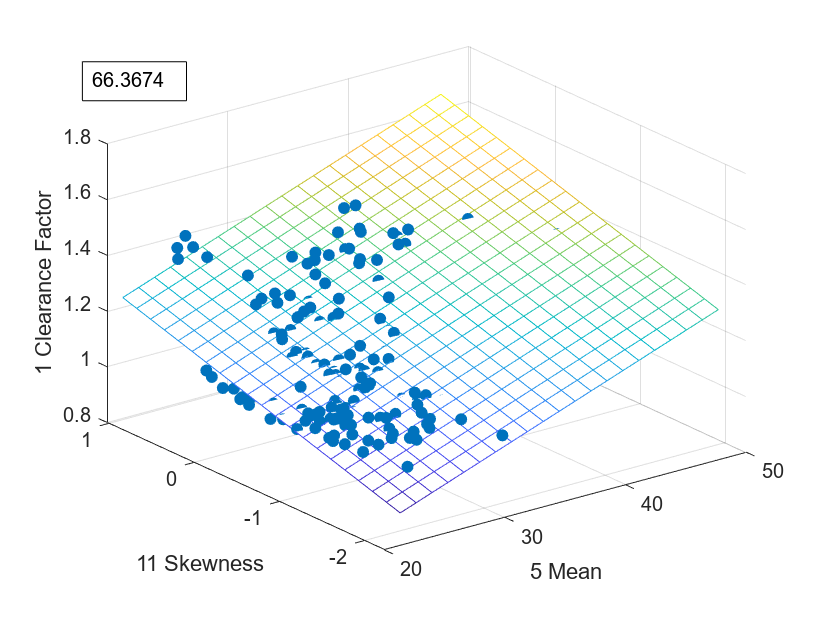

txtTitle = "21:28 Vibration measurements [mm/s]"

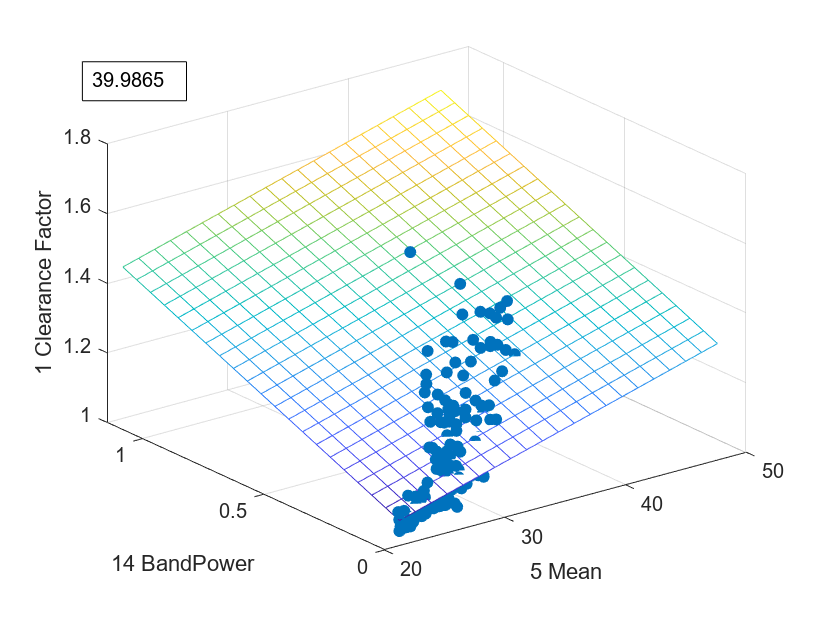

txtTitle = "21:28 Vibration measurements [mm/s]"

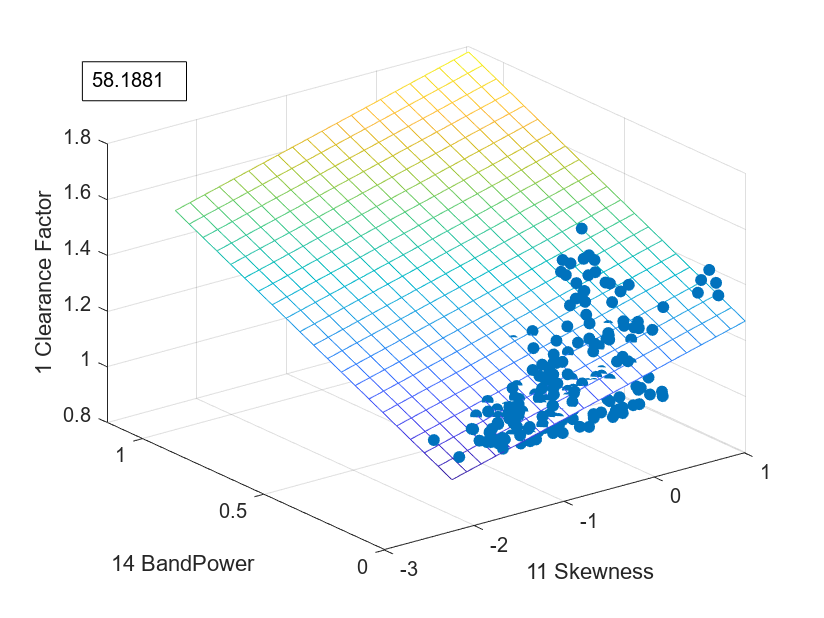

multivariateModelNum = 1;
if numOfSelectedFeatures > 2
    for index1 = 2 : numOfSelectedFeatures
        for index2 = index1+1 : numOfSelectedFeatures
            if selectedFeatureArray(index1) ~= selectedFeature && selectedFeatureArray(index2) ~= selectedFeature            
                Y_est = fnPlotModel3D( ...
                    selectedFeatureData{selectedFeatureIdx}, ...
                    selectedFeatureData{index1}, ...
                    selectedFeatureData{index2}, ...
                    sensorNames(selectedSignal), ...
                    FeatureNames(selectedFeatureArray(selectedFeatureIdx)), ...
                    FeatureNames(selectedFeatureArray(index1)), ...
                    FeatureNames(selectedFeatureArray(index2)));
                if (saveFigures == true)
                    filename = "..\Latex Document\figures\Models_Signal" + selectedSignal ...
                        + "Feature" + selectedFeature ...
                        + "_Multivariate" + multivariateModelNum;
                    export_fig(filename, '-eps', '-depsc');
                    multivariateModelNum = multivariateModelNum + 1;
                end
            end
        end
    end
end